**Example 05 Laoding of Kresling Origami Tube**

clear all;
clc;
close all;

Here we generate the geometry of the Kresling origami. This time, instead of entering the nodal coordinates manually node by node, we will do the modeling with an automated code. The equation of this system can be found in many papers on line. For example, the following links will lead you to two papers using Kresling origami for soft robot applications. You can find the definition of the geometry there.

[https://www.liebertpub.com/doi/abs/10.1089/soro.2020.0075](https://www.liebertpub.com/doi/abs/10.1089/soro.2020.0075)

[https://www.pnas.org/doi/full/10.1073/pnas.2013292117](https://www.pnas.org/doi/full/10.1073/pnas.2013292117)

% Define the nodal coordinate before meshing
R=50*10^(-3); % The radius of the Kresling pattern
H=50*10^(-3); % The height of each layer
theta=30/180*pi; % The twist between each layer
N=6; % The total number of side
M=1; % Number of section in the heigth direction

% Stiffness parameters of the structure
sprStiff=0.00001;
panelE=10*10^6;
panelv=0.3;
panelt=1*10^-3;

% Initialize objects
cst=Vec_Elements_CST;
rotSpr=Vec_Elements_RotSprings_4N;
node=Elements_Nodes;

Here, we first difine the geometry of this Kresling origami. The term $H$ is the height of the Kresling origami. The term $R$ is the radius. The angle $\theta \;$defines the twist between each layer. Here, we want to show you how we can write the geometry using for loop. This is a skill that is necessary when you work on larger scale FEM models. 

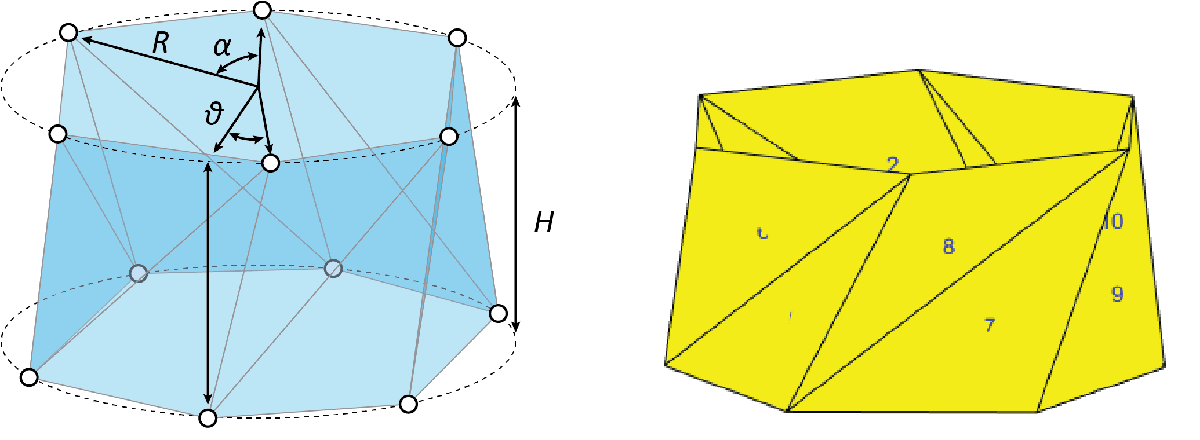

% Define the nodal coordinates
alpha=2*pi/N; % Secter angle
for i=1:M+1
    for j=1:N
        node.coordinates_mat=[node.coordinates_mat;
            R*cos(j*alpha+i*theta),R*sin(j*alpha+i*theta),(i-1)*H];
    end
end

The above code defines the nodal coordinates for the Kresling origami, using a for loop. The outer loop over "M" is the height direction while the inner loop "N" is used to find the nodes on each circle. the term "alpha" is used to locate the position of the node in the XY plane. With the nodal cooridnate finished, we will need to define the panels and the rotational springs. To write a for loop for these cases require some thinking to understand how the nodes are repeated. The following code provides a working template for you to get started. 

% set up panels for plotting
panelNum=0;
for i=1:M
    for j=1:N
        if j ~=N
            cst.cst_ijk_mat=[cst.cst_ijk_mat;
                (i-1)*N+j,(i-1)*N+j+1,(i)*N+j+1];
            panelNum=panelNum+1;
            cst.cst_ijk_mat=[cst.cst_ijk_mat;
                (i-1)*N+j,(i)*N+j,(i)*N+j+1];
            panelNum=panelNum+1;
        else
            cst.cst_ijk_mat=[cst.cst_ijk_mat;
                (i-1)*N+j,(i-1)*N+1,(i)*N+1];
            panelNum=panelNum+1;
            cst.cst_ijk_mat=[cst.cst_ijk_mat;
                (i-1)*N+j,(i)*N+j,(i)*N+1];
            panelNum=panelNum+1;
        end
    end
end

With the "ijk_mat" set up for the triangle panels, we define the properties for this panel.

% Set up th ematerial properties for the panels
cst.v_vec=panelv*ones(panelNum,1);
cst.E_vec=panelE*ones(panelNum,1);
cst.t_vec=panelt*ones(panelNum,1);

Similarly, the 4-node rotational springs can be set up using a for loop. The first for loop is used to create the 4-node rotational spring for a system within one layer. The second for loop create the 4-node spring for connecting adjacent layers.  

% This is used to generate the Kresling geometry for system 
% within each layer
for i=1:M
    for j=1:N
        if j ==1
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i-1)*N+N,(i-1)*N+j,(i)*N+j,(i)*N+j+1];
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i)*N+j,(i-1)*N+j,(i)*N+j+1,(i-1)*N+j+1];
        elseif j~=N
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i-1)*N+j-1,(i-1)*N+j,(i)*N+j,(i)*N+j+1];
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i)*N+j,(i-1)*N+j,(i)*N+j+1,(i-1)*N+j+1];
        else
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i-1)*N+j-1,(i-1)*N+j,(i)*N+j,(i)*N+1];
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i)*N+j,(i-1)*N+j,(i)*N+1,(i-1)*N+1];
        end
    end
end

% This is used to generate the 4-node spring for 
% connecting adjacent layers 
for i=1:M-1
    for j=1:N
        if j~=N
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i-1)*N+j,i*N+j,i*N+j+1,(i+1)*N+j+1];
        else
            rotSpr.node_ijkl_mat=[rotSpr.node_ijkl_mat;
                (i-1)*N+j,i*N+j,i*N+1,(i+1)*N+1];
        end
    end
end

rotSpr.rot_spr_K_vec=sprStiff*ones(M*(2*N)+N*(M-1),1);

Now thatwe had finished all the component, we can create the origami assembly and initialize the assembly using the following code here. 

assembly=Assembly_CST_Origami();
assembly.node=node;
assembly.cst=cst;
assembly.rotSpr=rotSpr;
assembly.InitializeAssembly()

Before we set up the nonlinear solvers, we do want to visually inspect the existing code to make sure that the generated geometry is indeed accurate. This is especially true when writing for loops for creating the simulation model

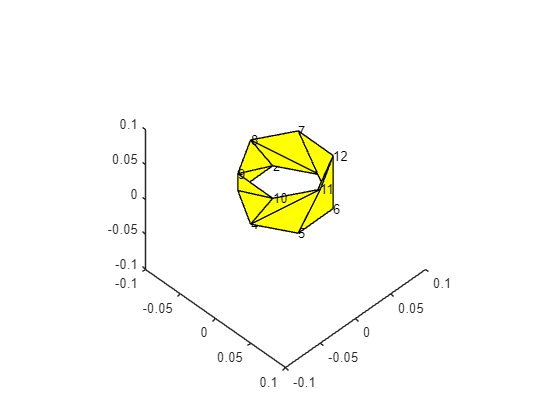

% set up the ploting object
plots=Plot_CST_Origami();
plots.displayRange=0.1;
plots.displayRangeRatio=1;
plots.assembly=assembly;

% Plot the numbering of springs and cst
plots.Plot_Shape_NodeNumber()

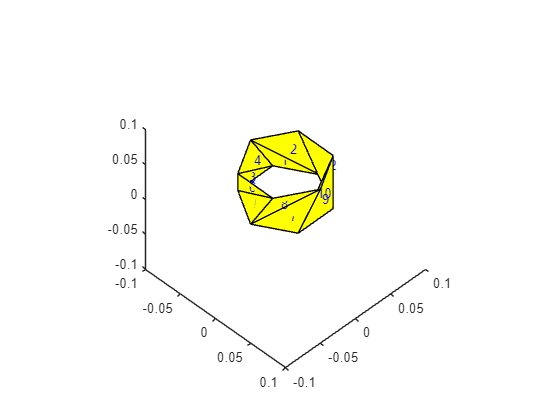

plots.Plot_Shape_CSTNumber()

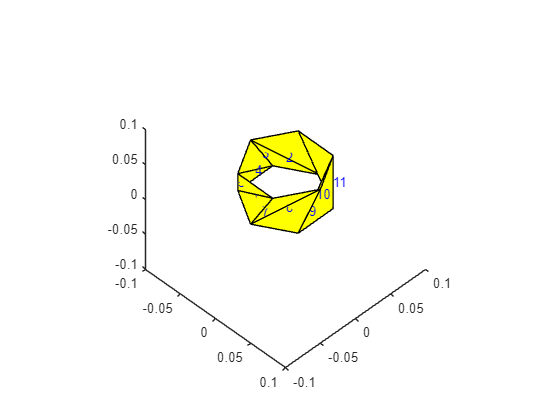

plots.Plot_Shape_SprNumber()

The Kresling origami is known for having bistable mechanical loading behaviors - they tend to have a stable compressed state and a stable extended state. The default example demonstrated here is one of this bistable Kresling design. Thus, the loading motion needs to be tracked using a displacement-controlled solver. This displacement controlled solver is able to capture the nonlinear snap through behaviors in the bistable system. A good resorce to learn about all different nonlinear equilibrium solution method can be found in:

[https://asmedigitalcollection.asme.org/appliedmechanicsreviews/article/64/4/040803/463373/A-Unified-Library-of-Nonlinear-Solution-Schemes](https://asmedigitalcollection.asme.org/appliedmechanicsreviews/article/64/4/040803/463373/A-Unified-Library-of-Nonlinear-Solution-Schemes)

Setting up the displacement controlled solver is the same as setting up the Newton-Raphson solver. 

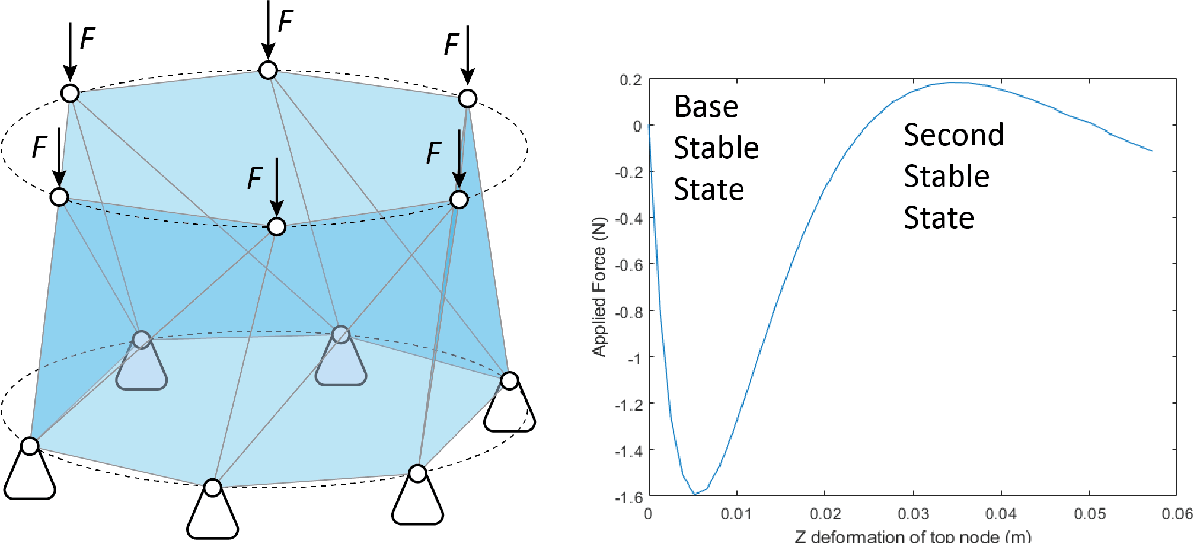

% Define the displacement controlled solver
dc=Solver_DC;
dc.assembly=assembly;
dc.supp=[1,1,1,1;
         2,1,1,1;
         3,1,1,1;
         4,1,1,1;
         5,1,1,1;
         6,1,1,1];

% we will need to select one nodal displacement for 
% referencing to run the solver
dc.selectedRefDisp=[6*M+1,3];

% Loading force
force=-1;
dc.load=[6*M+1,0,0,force;
         6*M+2,0,0,force;
         6*M+3,0,0,force;
         6*M+4,0,0,force;
         6*M+5,0,0,force;
         6*M+6,0,0,force;];

% other controller parameters
dc.increStep=30;
dc.tol=10^-6;
dc.iterMax=50;

% Solve for the deformation history
Uhis=dc.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 5.774845e-03
    Iteration = 2, R = 1.461956e-04
    Iteration = 3, R = 7.278557e-07
Icrement = 2
    Iteration = 1, R = 5.774845e-03
    Iteration = 2, R = 1.518017e-04
    Iteration = 3, R = 9.045547e-07
Icrement = 3
    Iteration = 1, R = 5.774845e-03
    Iteration = 2, R = 1.556467e-04
    Iteration = 3, R = 1.053998e-06
    Iteration = 4, R = 6.203433e-09
Icrement = 4
    Iteration = 1, R = 5.774845e-03
    Iteration = 2, R = 1.580327e-04
    Iteration = 3, R = 1.318345e-06
    Iteration = 4, R = 1.546843e-08
Icrement = 5
    Iteration = 1, R = 5.774845e-03
    Iteration = 2, R = 1.592838e-04
    Iteration = 3, R = 1.763962e-06
    Iteration = 4, R = 3.239326e-08
Icrement = 6
    Iteration = 1, R = 5.774845e-03
    Iteration = 2, R = 1.596549e-04
    Iteration = 3, R = 2.343707e-06
    Iteration = 4, R = 5.639456e-08
Icrement = 7
    Iteration = 1, R = 5.774845e-03
    Iteration = 2, R = 1.593474e-04
    Iteration = 3, R = 

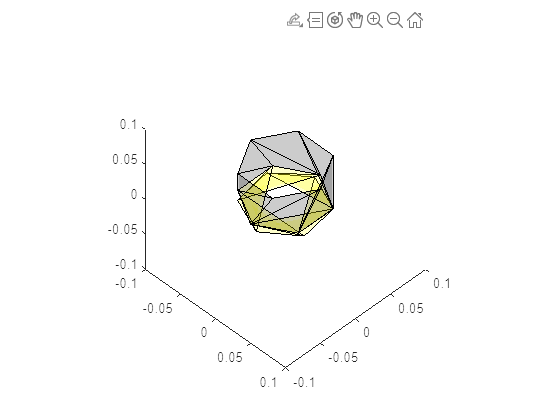

plots.Plot_DeformedShape(squeeze(Uhis(end,:,:)));

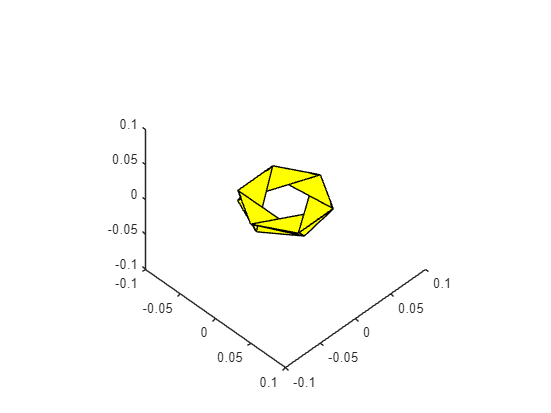

plots.fileName='Loading_Kresling_Origami.gif';
plots.Plot_DeformedHis(Uhis);

The deformation history is shown below:

## 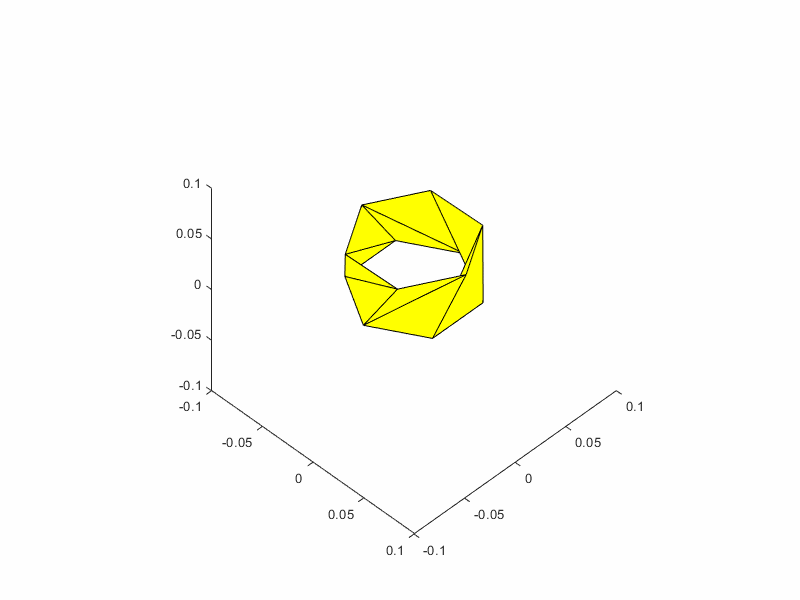

We hope to further plot the force-displacement curve for this Kresling origami. We will use the deformation history "Uhis" and the "SolveFK" function in the assemly to do this. Please note that the current simulation is for a elastic body - so the reaction forces are uniquely defined based on the deformation information. This uniqueness is not longer hold true when we start doing nonlinear material models.  

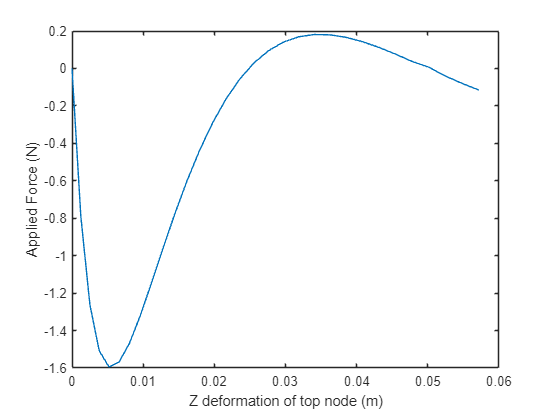

% Set up the storage matrix
forceHis=zeros(dc.increStep,1);
UrefHis=zeros(dc.increStep,1);

% Find the force-displacement information
for i=1:dc.increStep
    [F,K]=assembly.SolveFK(squeeze(Uhis(i,:,:)));
    UrefHis(i)=Uhis(i,dc.selectedRefDisp(1),dc.selectedRefDisp(2));
    forceHis(i)=F(dc.selectedRefDisp(2)+(dc.selectedRefDisp(1)-1)*3);
end

figure
UrefHis=[0;UrefHis];
forceHis=[0;forceHis];
plot(-UrefHis,forceHis)
xlabel('Z deformation of top node (m)') 
ylabel('Applied Force (N)') 